Load the data. Note that the data is not a correlation matrix to start.

clear all
load('fed_fast_refed.mat');
fed = Fed_Fast_Refed{1};
fast = Fed_Fast_Refed{2};
refed = Fed_Fast_Refed{3};

Build a correlation matrix with the diagonal elements removed.

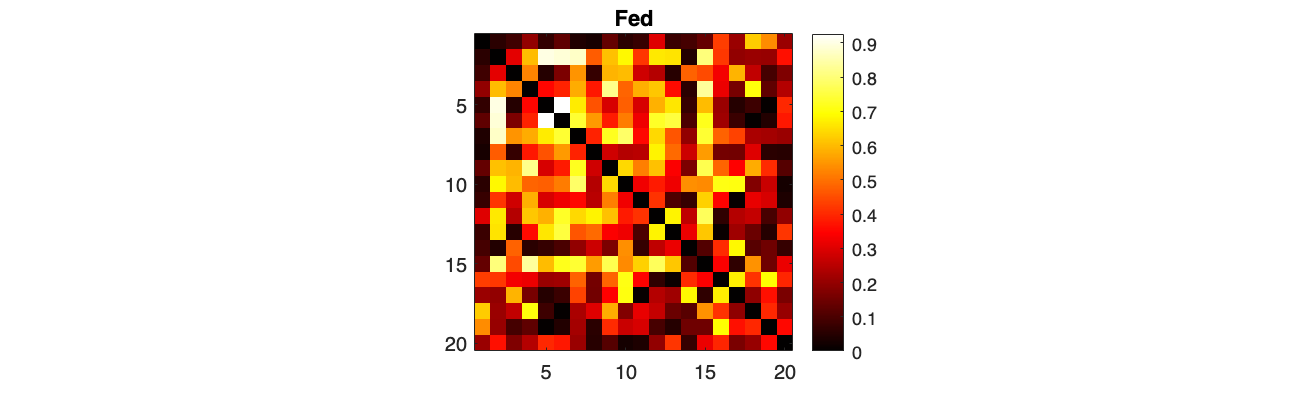

% make a correlation matrix
corrFed = abs(corrcoef(fed) - eye(size(fed, 2)));

% plot the correlation matrix
colormap hot;
imagesc(corrFed);
daspect([1 1 1]); % force the image to a nice square
title("Fed");
colorbar;
fig = gcf; % resize the figure 
fig.Position(3:4)=[1000,300];

% make a correlation matrix
corrFast = abs(corrcoef(fast) - eye(size(fast, 2)));

% plot the correlation matrix
colormap hot;
imagesc(corrFast);
daspect([1 1 1]); % force the image to a nice square
title("Fast");
colorbar;
fig = gcf; % resize the figure 
fig.Position(3:4)=[1000,300];


% make a correlation matrix
corrReFed = abs(corrcoef(refed) - eye(size(refed, 2)));

% plot the correlation matrix
colormap hot;
imagesc(corrReFed);
daspect([1 1 1]); % force the image to a nice square
title("ReFed");
colorbar;
fig = gcf; % resize the figure 
fig.Position(3:4)=[1000,300];

Convert a matrix of floating point numbers to an unwieghted adjacency based on a threshold, `t`. Note that this is a random matrix, but could easily be substituted for, say, a correlation matrix :)

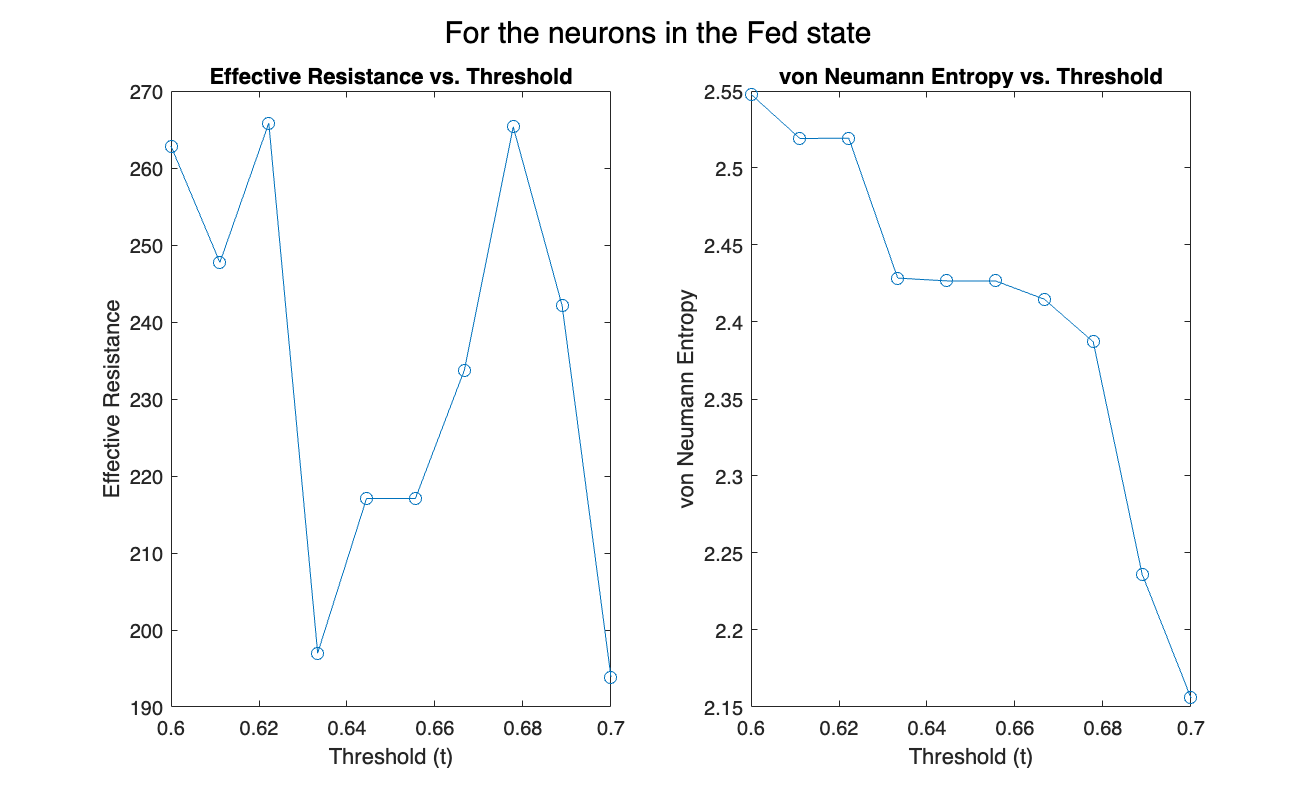

rng(0);
t = 0.6; % change this value and see what happens

% create a binary matrix using t as the threshold value
Atil1 = corrFed;
Atil1(Atil1 >= t) = 1;
Atil1(Atil1 < t) = 0;

% plot them both
subplot(1, 2, 1);
imagesc(corrFed);
daspect([1 1 1]);
title('Fed');
colorbar;

subplot(1, 2, 2);
imagesc(Atil1);
daspect([1 1 1]);
title('Thresholded Matrix of Fed');
colorbar;
% resize the figure 
fig1 = gcf; 
fig1.Position(3:4)=[1000,600];
% t = 0.6; % change this value and see what happens
% 
% % create a binary matrix using t as the threshold value
% Atil1 = corrFed;
% Atil1(Atil1 >= t) = 1;
% Atil1(Atil1 < t) = 0;
% degreeFed = sum(Atil1, 2);
% 
% D1 = diag(degreeFed);
% L1 = D1 - Atil1;
% n = size(L1, 1);
% eigenvalues1 = eig(L1);
% eps = 0.001;
% eigenvalues1 = eigenvalues1(eigenvalues1 > eps);
% 
% R1 = n * sum(1 ./ eigenvalues1);
% disp(['The total effective resistance of the graph is: ' num2str(R1)]);
% % eigenvalues1b = eig(L1);
% 
% eigenvalues1(1) = []; % Remove the first eigenvalue
% normalized_eigenvalues1 = eigenvalues1 / sum(eigenvalues1);
% 
% normalized_eigenvalues1(normalized_eigenvalues1 == 0) = 1;
% von_Neumann_entropy = -sum(normalized_eigenvalues1 .* log(normalized_eigenvalues1));
% 
% % Display the von Neumann entropy
% disp(['The von Neumann entropy of the graph is: ' num2str(von_Neumann_entropy)]);
% Predefine the range of t values and initialize arrays to store the results
t_values = linspace(0.6, 0.7, 10);
effective_resistances = zeros(1, length(t_values));
entropies = zeros(1, length(t_values));

% Loop over each t value
for i = 1:length(t_values)
    t = t_values(i);
    
    % Threshold the matrix
    Atil1 = corrFed >= t;
    degreeFed = sum(Atil1, 2);
    
    % Compute the Laplacian
    D1 = diag(degreeFed);
    L1 = D1 - Atil1;
    n = size(L1, 1);
    
    % Compute eigenvalues and effective resistance
    eigenvalues1 = eig(L1);
    eigenvalues1 = eigenvalues1(eigenvalues1 > eps);
    effective_resistances(i) = n * sum(1 ./ eigenvalues1);
    
    % Compute the von Neumann entropy
    eigenvalues1(1) = []; % Remove the first eigenvalue
    normalized_eigenvalues1 = eigenvalues1 / sum(eigenvalues1);
    normalized_eigenvalues1(normalized_eigenvalues1 <= 0) = 1;  % Avoid log(0)
    entropies(i) = -sum(normalized_eigenvalues1 .* log(normalized_eigenvalues1));
end

% Plotting the results
subplot(1, 2, 1);
plot(t_values, effective_resistances, '-o');
xlabel('Threshold (t)');
ylabel('Effective Resistance');
title('Effective Resistance vs. Threshold');

subplot(1, 2, 2);
plot(t_values, entropies, '-o');
xlabel('Threshold (t)');
ylabel('von Neumann Entropy');
title('von Neumann Entropy vs. Threshold');
sgtitle('For the neurons in the Fed state');

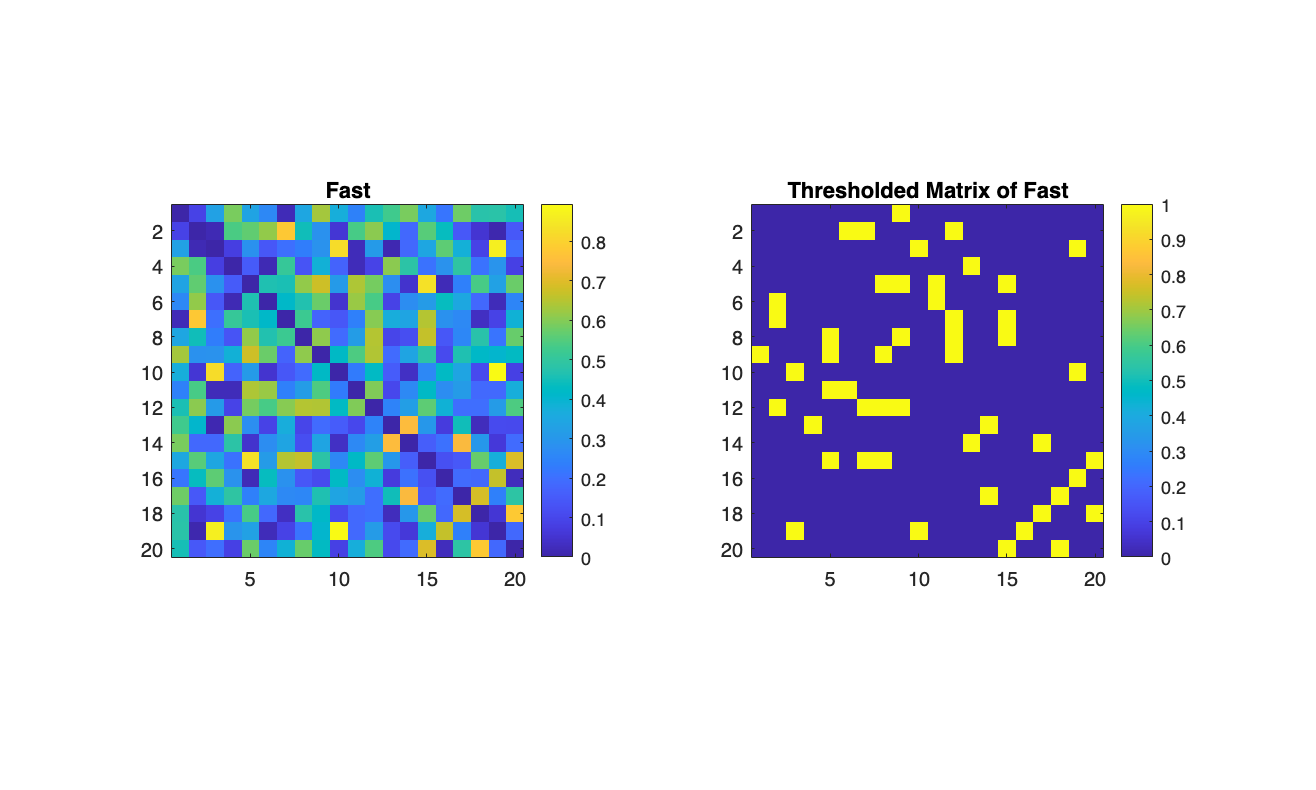



figure;
t = 0.6; % change this value and see what happens

% create a binary matrix using t as the threshold value
Atil2 = corrFast;
Atil2(Atil2 >= t) = 1;
Atil2(Atil2 < t) = 0;

% plot them both
subplot(1, 2, 1);
imagesc(corrFast);
daspect([1 1 1]);
title('Fast');
colorbar;

subplot(1, 2, 2);
imagesc(Atil2);
daspect([1 1 1]);
title('Thresholded Matrix of Fast');
colorbar;
% resize the figure 
fig2 = gcf; 
fig2.Position(3:4)=[1000,600];

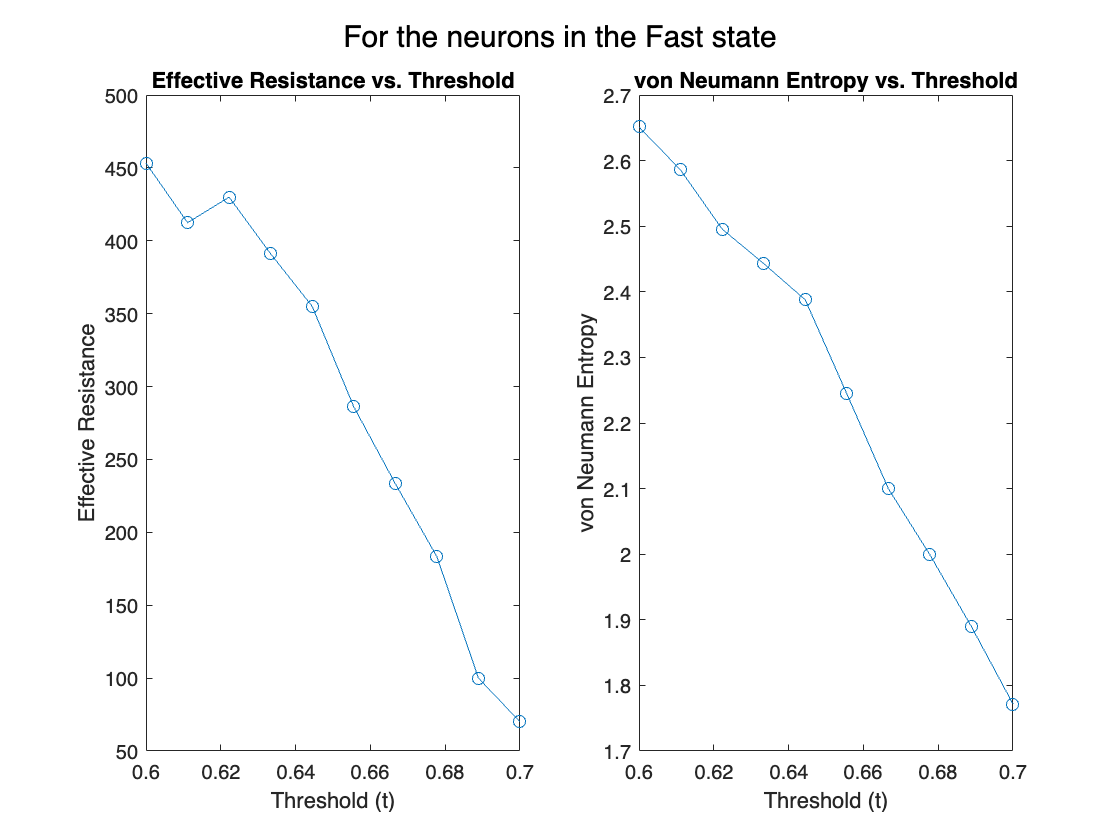


% degreeFast = sum(Atil2, 2);
% 
% D2 = diag(degreeFast);
% L2 = D2 - Atil2;
% eigenvalues2 = eig(L2);
% eigenvalues2 = eigenvalues2(eigenvalues2 > eps);
% R2 = n * sum(1 ./ eigenvalues2);
% disp(['The total effective resistance of the graph is: ' num2str(R2)]);
figure;
t_values = linspace(0.6, 0.7, 10);
effective_resistances = zeros(1, length(t_values));
entropies = zeros(1, length(t_values));

% Loop over each t value
for i = 1:length(t_values)
    t = t_values(i);
    
    % Threshold the matrix
    Atil2 = corrFast >= t;
    degreeFast = sum(Atil2, 2);
    
    % Compute the Laplacian
    D2 = diag(degreeFast);
    L2 = D2 - Atil2;
    n = size(L2, 1);
    
    % Compute eigenvalues and effective resistance
    eigenvalues2 = eig(L2);
    eigenvalues2 = eigenvalues2(eigenvalues2 > eps);
    effective_resistances(i) = n * sum(1 ./ eigenvalues2);
    
    % Compute the von Neumann entropy
    eigenvalues2(1) = []; % Remove the first eigenvalue
    normalized_eigenvalues2 = eigenvalues2 / sum(eigenvalues2);
    normalized_eigenvalues2(normalized_eigenvalues2 <= 0) = 1;  % Avoid log(0)
    entropies(i) = -sum(normalized_eigenvalues2 .* log(normalized_eigenvalues2));
end

% Plotting the results
subplot(1, 2, 1);
plot(t_values, effective_resistances, '-o');
xlabel('Threshold (t)');
ylabel('Effective Resistance');
title('Effective Resistance vs. Threshold');

subplot(1, 2, 2);
plot(t_values, entropies, '-o');
xlabel('Threshold (t)');
ylabel('von Neumann Entropy');
title('von Neumann Entropy vs. Threshold');

sgtitle('For the neurons in the Fast state');

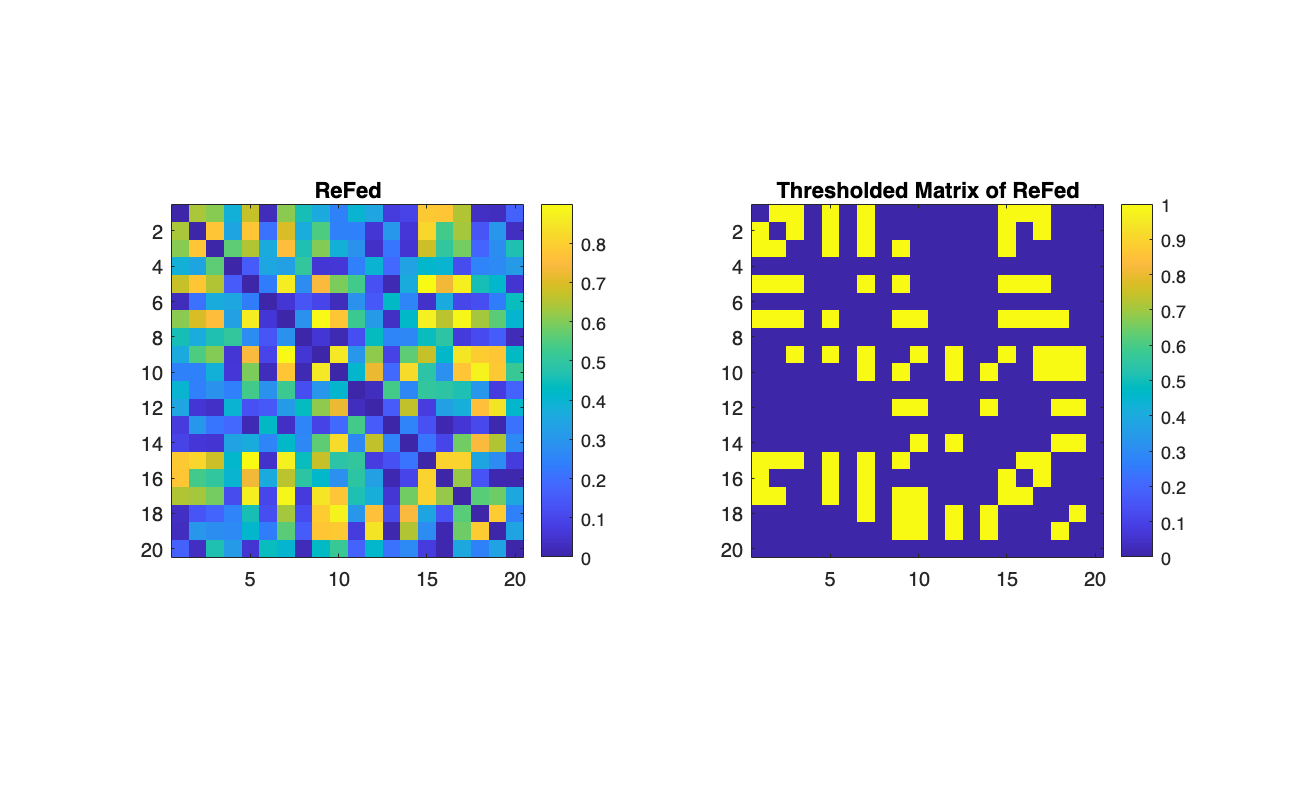


figure;
t = 0.6; % change this value and see what happens
% 
% create a binary matrix using t as the threshold value
Atil3 = corrReFed;
Atil3(Atil3 >= t) = 1;
Atil3(Atil3 < t) = 0;

% plot them both
subplot(1, 2, 1);
imagesc(corrReFed);
daspect([1 1 1]);
title('ReFed');
colorbar;

subplot(1, 2, 2);
imagesc(Atil3);
daspect([1 1 1]);
title('Thresholded Matrix of ReFed');
colorbar;
% resize the figure 
fig3 = gcf; 
fig3.Position(3:4)=[1000,600];

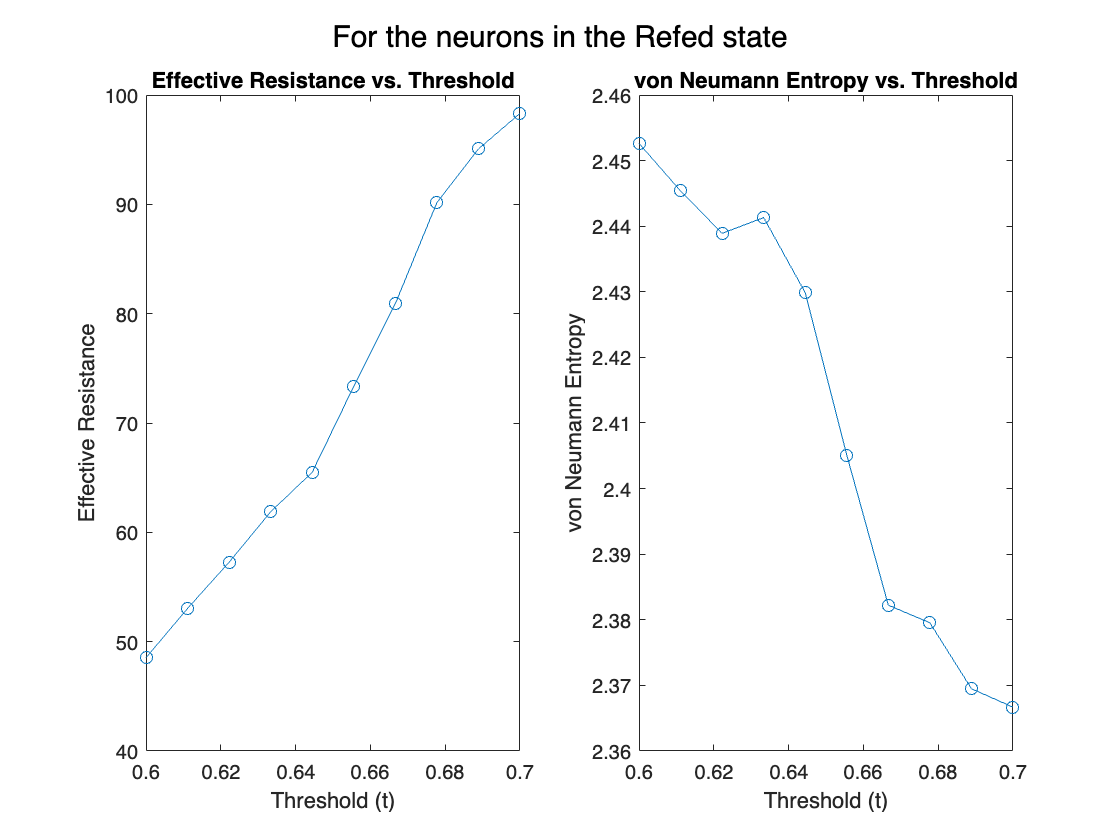

% degreeReFed = sum(Atil3, 2);
% 
% D3 = diag(degreeReFed);
% L3 = D3 - Atil3;
% eigenvalues3 = eig(L3);
% eigenvalues3 = eigenvalues3(eigenvalues3 > eps);
% R3 = n * sum(1 ./ eigenvalues3);
% disp(['The total effective resistance of the graph is: ' num2str(R3)]);

figure;
t_values = linspace(0.6, 0.7, 10);
effective_resistances = zeros(1, length(t_values));
entropies = zeros(1, length(t_values));

% Loop over each t value
for i = 1:length(t_values)
    t = t_values(i);
    
    % Threshold the matrix
    Atil3 = corrReFed >= t;
    degreeReFed = sum(Atil3, 2);
    
    % Compute the Laplacian
    D3 = diag(degreeReFed);
    L3 = D3 - Atil3;
    n = size(L3, 1);
    
    % Compute eigenvalues and effective resistance
    eigenvalues3 = eig(L3);
    eigenvalues3 = eigenvalues3(eigenvalues3 > eps);
    effective_resistances(i) = n * sum(1 ./ eigenvalues3);
    
    % Compute the von Neumann entropy
    eigenvalues3(1) = []; % Remove the first eigenvalue
    normalized_eigenvalues3 = eigenvalues3 / sum(eigenvalues3);
    normalized_eigenvalues3(normalized_eigenvalues3 <= 0) = 1;  % Avoid log(0)
    entropies(i) = -sum(normalized_eigenvalues3 .* log(normalized_eigenvalues3));
end

% Plotting the results
subplot(1, 2, 1);
plot(t_values, effective_resistances, '-o');
xlabel('Threshold (t)');
ylabel('Effective Resistance');
title('Effective Resistance vs. Threshold');

subplot(1, 2, 2);
plot(t_values, entropies, '-o');
xlabel('Threshold (t)');
ylabel('von Neumann Entropy');
title('von Neumann Entropy vs. Threshold');

sgtitle('For the neurons in the Refed state');